# Regression tutorial 2: Inferring interactions

In the previous tutorial, we showed how autoregression can be used to mitigate spurious correlations among independent timeseries. Here, we look at the positive case -- can autoregression be used to detect interactions?

need to generate dynamics that are stable and "interacting"

how to define interactions?

start with small, simple network?

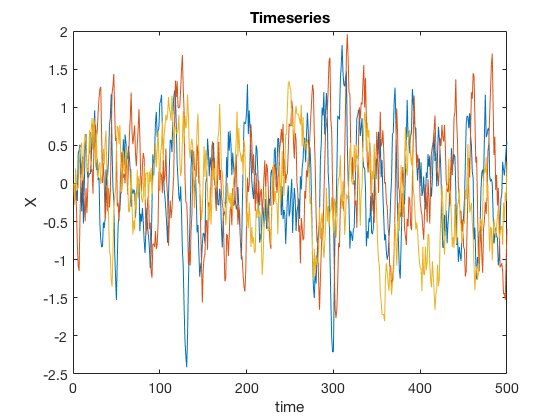

clear;

N = 3; % number of "species"
NT = 500; % number of timepoints

M = [-1 2 0; -2 -1 0; 0 0 -1];

% we'll use a very simple discrete dynamical model
X = zeros(NT,N);
for i = 2:NT
    X(i,:) = X(i-1,:) + X(i-1,:)*M/N^2 + 0.5*(2*rand(1,N)-1);
end

clf;
plot(X);
xlabel('time');
ylabel('X');
title('Timeseries');
set(gca,'FontSize',14);

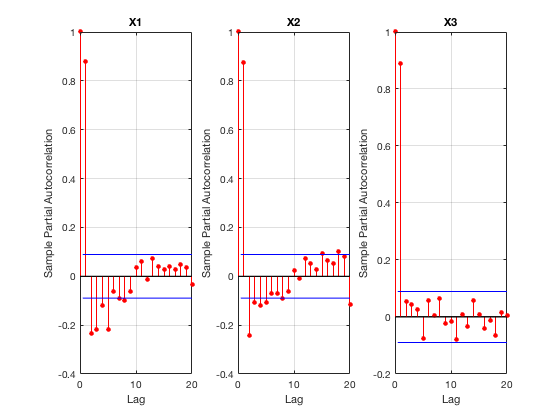

clf;
for i = 1:N
    subplot(1,N,i);
    parcorr(X(:,i));
    title(sprintf('X%d',i));
end

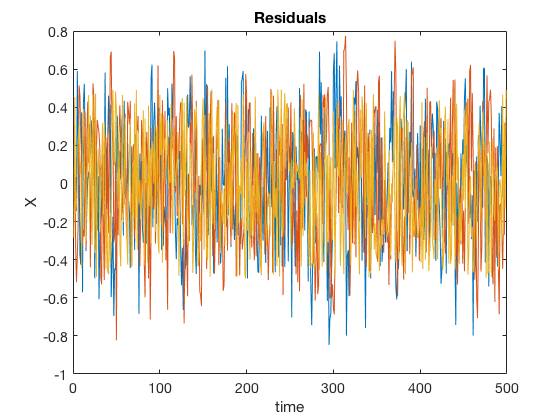

X1 = X(1:end-1,:);
X2 = X(2:end,:);
phi1 = sum((X1-mean(X1)).*(X2-mean(X2)))./sum(X1.^2-mean(X1).^2);
Xresidual = X2 - X1.*phi1;

clf;
figure();
plot(Xresidual);
xlabel('time');
ylabel('X');
title('Residuals');
set(gca,'FontSize',14);

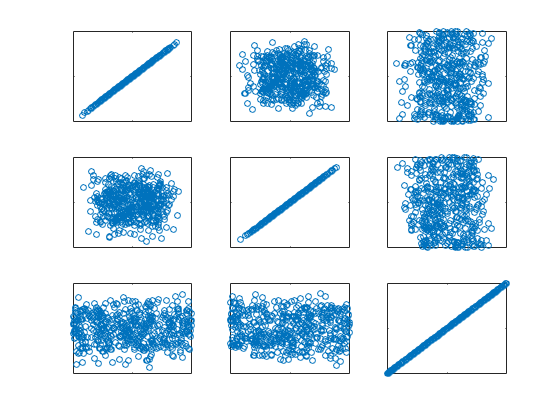


clf;
figure();
k = 1;
for i = 1:N
    for j = 1:N
        subplot(N,N,k)
        plot(Xresidual(:,i),Xresidual(:,j),'o');
        set(gca,'XTickLabel',[],'YTickLabel',[]);
        k = k+1;
    end
end